# Measuring how the responses of individual cells change between high and low contrast stimuli

Cell attached recordings only

downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
mustHave_2b = {'Extracellular', '_Intensity0d1'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upPDs = [];
upPDs_LowC = [];
upTCAreas = [];
upTCAreas_LowC = [];
upNormedAreas = [];
upNormedAreas_LowC = [];
upDSIs = [];
upDSIs_LowC = [];
upDSISimple = [];
upDSISimple_LowC = [];
upFailures = [];
upFailures_LowC = [];
upVariance = [];
upVariance_LowC = [];
%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    
    %Do the high contrast condition first
    PD = mod(loc.Analysis_Results.PreferredDirection, 360);
    upPDs(end + 1) = PD;
    medianResponses = cellfun(@median, loc.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    
    %Check to see if there are no stimuli where the median response is
    %greater than 1 spike. If this is the case, the response is considered
    %a "Failure"
    if max(medianResponses) < 1
        upFailures(end + 1) = 1; %mark that this cell was a failure
        upDSIs(end + 1) = 1; %DSI is 1 for failures
        NormedArea = 0; %Normed area is 0 for failures
        upDSISimple(end + 1) = 1;
        tcArea = 0; %total area is 0 for failures
        upVariance(end + 1) = 0;
        %If the stimulus wasn't a "failure", then calculate the metrics
        %organically
    else
        upFailures(end + 1) = 0;
        ND = mod(PD-180, 360);
        
        upDSIs(end + 1) = loc.Analysis_Results.DSI;
        
        %get tuning curve info
        [directions, leaf] = sort(loc.Analysis_Results.Orientation);
        tuningCurve = loc.Analysis_Results.mean_spikesByOrientation(leaf);
        
        PDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD);
        NDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], ND);
        
        tcArea = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
        NormedArea = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse)/360;
        
        upDSISimple(end + 1) = (PDResponse-NDResponse)/(PDResponse+NDResponse);
        upVariance(end + 1) = mean(loc.Analysis_Results.std_spikesByOrientation.^2);
    end
    upTCAreas(end + 1) = tcArea;
    upNormedAreas(end + 1) = NormedArea;
    
    
    clear directions leaf tuningCurve
    
    %Repeat the entire process for the low contrast condition
    PD_LowC = mod(loc_LowC.Analysis_Results.PreferredDirection, 360);
    upPDs_LowC(end + 1) = PD_LowC;
    
    medianResponses = cellfun(@median, loc_LowC.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    
    if max(medianResponses) < 1
        upFailures_LowC(end + 1) = 1;
        upDSIs_LowC(end + 1) = 1;
        NormedArea_LowC = 0;
        upDSISimple_LowC(end + 1) = 1;
        tcArea_LowC = 0;
        upVariance_LowC(end + 1) = 0;
    else
        upFailures_LowC(end + 1) = 0;
        ND_LowC = mod(PD_LowC-180, 360);
        
        upDSIs_LowC(end + 1) = loc_LowC.Analysis_Results.DSI;
        
        [directions, leaf] = sort(loc_LowC.Analysis_Results.Orientation);
        tuningCurve = loc_LowC.Analysis_Results.mean_spikesByOrientation(leaf);
        
        PDResponse_LowC = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD_LowC);
        NDResponse_LowC = interp1([directions, 360], [tuningCurve, tuningCurve(1)], ND_LowC);
        tcArea_LowC = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
        NormedArea_LowC = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse_LowC)/360;
        upDSISimple_LowC(end + 1) = (PDResponse_LowC-NDResponse_LowC)/(PDResponse_LowC+NDResponse_LowC);
        upVariance_LowC(end + 1) = mean(loc_LowC.Analysis_Results.std_spikesByOrientation.^2);
    end
    upTCAreas_LowC(end + 1) = tcArea_LowC;
    upNormedAreas_LowC(end + 1) = NormedArea_LowC;
end


downPDs = [];
downPDs_LowC = [];
downTCAreas = [];
downTCAreas_LowC = [];
downNormedAreas = [];
downNormedAreas_LowC = [];
downDSIs = [];
downDSIs_LowC = [];
downDSISimple = [];
downDSISimple_LowC = [];
downFailures = [];
downFailures_LowC = [];
downVariance = [];
downVariance_LowC = [];
%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    
    %Do the high contrast condition first
    PD = mod(loc.Analysis_Results.PreferredDirection, 360);
    downPDs(end + 1) = PD;
    medianResponses = cellfun(@median, loc.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    
    %Check to see if there are no stimuli where the median response is
    %greater than 1 spike. If this is the case, the response is considered
    %a "Failure"
    if max(medianResponses) < 1
        downFailures(end + 1) = 1; %mark that this cell was a failure
        downDSIs(end + 1) = 1; %DSI is 1 for failures
        NormedArea = 0; %Normed area is 0 for failures
        downDSISimple(end + 1) = 1;
        tcArea = 0; %total area is 0 for failures
        downVariance(end + 1) = 0;
        
        %If the stimulus wasn't a "failure", then calculate the metrics
        %organically
    else
        downFailures(end + 1) = 0;
        ND = mod(PD-180, 360);
        
        downDSIs(end + 1) = loc.Analysis_Results.DSI;
        
        %get tuning curve info
        [directions, leaf] = sort(loc.Analysis_Results.Orientation);
        tuningCurve = loc.Analysis_Results.mean_spikesByOrientation(leaf);
        
        PDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD);
        NDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], ND);
        
        tcArea = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
        NormedArea = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse)/360;
        
        downDSISimple(end + 1) = (PDResponse-NDResponse)/(PDResponse+NDResponse);
        downVariance = mean(loc.Analysis_Results.std_spikesByOrientation.^2);
    end
        
    downTCAreas(end + 1) = tcArea;
    downNormedAreas(end + 1) = NormedArea;
    
    
    clear directions leaf tuningCurve
    
    %Repeat the entire process for the low contrast condition
    PD_LowC = mod(loc_LowC.Analysis_Results.PreferredDirection, 360);
    downPDs_LowC(end + 1) = PD_LowC;
    
    medianResponses = cellfun(@median, loc_LowC.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    
    if max(medianResponses) < 1
        downFailures_LowC(end + 1) = 1;
        downDSIs_LowC(end + 1) = 1;
        NormedArea_LowC = 0;
        downDSISimple_LowC(end + 1) = 1;
        tcArea_LowC = 0;
        downVariance_LowC(end + 1) = 0;
    else
        downFailures_LowC(end + 1) = 0;
        ND_LowC = mod(PD_LowC-180, 360);
        
        downDSIs_LowC(end + 1) = loc_LowC.Analysis_Results.DSI;
        
        [directions, leaf] = sort(loc_LowC.Analysis_Results.Orientation);
        tuningCurve = loc_LowC.Analysis_Results.mean_spikesByOrientation(leaf);
        
        PDResponse_LowC = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD_LowC);
        NDResponse_LowC = interp1([directions, 360], [tuningCurve, tuningCurve(1)], ND_LowC);
        tcArea_LowC = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
        NormedArea_LowC = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse_LowC)/360;
        downDSISimple_LowC(end + 1) = (PDResponse_LowC-NDResponse_LowC)/(PDResponse_LowC+NDResponse_LowC);
        downVariance_LowC(end + 1) = mean(loc_LowC.Analysis_Results.std_spikesByOrientation.^2);
    end

    downTCAreas_LowC(end + 1) = tcArea_LowC;
    downNormedAreas_LowC(end + 1) = NormedArea_LowC;
end

## Figures

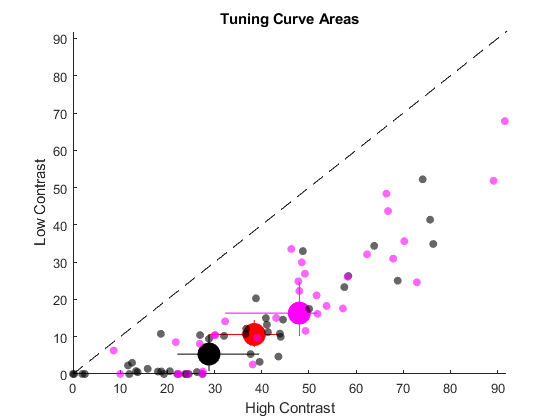

% figure
% title('Tuning Curve Areas For High/Low Contrast')
% hold on
% for i = 1:numel(upTCAreas)
%     p = plot([0.5, 1.5], [upTCAreas(i), upTCAreas_LowC(i)], 'Color', [0, 0, 0], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [0, 0, 0];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% for i = 1:numel(downTCAreas)
%     p = plot([0.5, 1.5], [downTCAreas(i), downTCAreas_LowC(i)], 'Color', [1, 0, 1], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [1, 0, 1];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% xlim([0.3, 1.7])
% ylabel('Total Area')
% xticks([0.5, 1.5])
% xticklabels({'High Contrast', 'Low Contrast'})
medianUpX = median(upTCAreas);
medianUpY = median(upTCAreas_LowC);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap(upTCAreas, 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap(upTCAreas_LowC, 10000);

medianDownX = median(downTCAreas);
medianDownY = median(downTCAreas_LowC);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap(downTCAreas, 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap(downTCAreas_LowC, 10000);

overallMedianX = median([upTCAreas, downTCAreas]);
overallMedianY = median([upTCAreas_LowC, downTCAreas_LowC]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upTCAreas, downTCAreas], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upTCAreas_LowC, downTCAreas_LowC], 10000);

figure
title('Tuning Curve Areas')
hold on
plot([0, 92], [0, 92], '--k')
scatter(medianUpX, medianUpY, 300, 'filled', 'k')
plot([-xUpER1, xUpER2]+medianUpX, [medianUpY, medianUpY], 'k')
plot([medianUpX, medianUpX], [-yUpER1, yUpER2] + medianUpY, 'k')
scatter(medianDownX, medianDownY, 300, 'filled', 'm')
plot([-xDownER1, xDownER2]+medianDownX, [medianDownY, medianDownY], 'm')
plot([medianDownX, medianDownX], [-yDownER1, yDownER2] + medianDownY, 'm')
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')

scatter(upTCAreas, upTCAreas_LowC, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downTCAreas, downTCAreas_LowC, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 92])
ylim([0, 92])

p_total =  signrank([upTCAreas, downTCAreas], [upTCAreas_LowC, downTCAreas_LowC])

p_total = 1.1491e-14

p_high = ranksum(upTCAreas, downTCAreas)

p_high = 0.0052

p_low = ranksum(upTCAreas_LowC, downTCAreas_LowC)

p_low = 0.0091

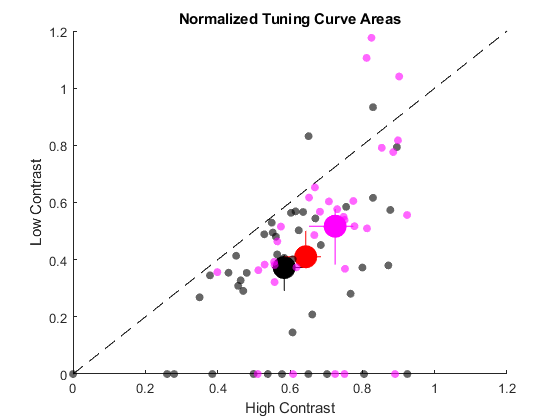


% figure
% title('Normalized Tuning Curve Areas For High/Low Contrast')
% hold on
% for i = 1:numel(upNormedAreas)
%     p = plot([0.5, 1.5], [upNormedAreas(i), upNormedAreas_LowC(i)], 'Color', [0, 0, 0], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [0, 0, 0];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% for i = 1:numel(downNormedAreas)
%     p = plot([0.5, 1.5], [downNormedAreas(i), downNormedAreas_LowC(i)], 'Color', [1, 0, 1], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [1, 0, 1];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% xlim([0.3, 1.7])
% ylabel('Area of the Normalized Curve')
% xticks([0.5, 1.5])
% xticklabels({'High Contrast', 'Low Contrast'})
medianUpX = median(upNormedAreas);
medianUpY = median(upNormedAreas_LowC);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap(upNormedAreas, 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap(upNormedAreas_LowC, 10000);

medianDownX = median(downNormedAreas);
medianDownY = median(downNormedAreas_LowC);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap(downNormedAreas, 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap(downNormedAreas_LowC, 10000);

overallMedianX = median([upNormedAreas, downNormedAreas]);
overallMedianY = median([upNormedAreas_LowC, downNormedAreas_LowC]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upNormedAreas, downNormedAreas], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upNormedAreas_LowC, downNormedAreas_LowC], 10000);


figure
title('Normalized Tuning Curve Areas')
hold on
plot([0, 1.2], [0, 1.2], '--k')
scatter(medianUpX, medianUpY, 300, 'filled', 'k')
plot([-xUpER1, xUpER2]+medianUpX, [medianUpY, medianUpY], 'k')
plot([medianUpX, medianUpX], [-yUpER1, yUpER2] + medianUpY, 'k')
scatter(medianDownX, medianDownY, 300, 'filled', 'm')
plot([-xDownER1, xDownER2]+medianDownX, [medianDownY, medianDownY], 'm')
plot([medianDownX, medianDownX], [-yDownER1, yDownER2] + medianDownY, 'm')
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')

scatter(upNormedAreas, upNormedAreas_LowC, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downNormedAreas, downNormedAreas_LowC, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 1.2])
ylim([0, 1.2])

p_total =  signrank([upNormedAreas, downNormedAreas], [upNormedAreas_LowC, downNormedAreas_LowC])

p_total = 1.7025e-11

p_high = ranksum(upNormedAreas, downNormedAreas)

p_high = 0.0031

p_low = ranksum(upNormedAreas_LowC, downNormedAreas_LowC)

p_low = 0.0082

%proportion over unity for chi squared test with spikes:
overUnity_NormedArea = [upNormedAreas downNormedAreas] > [upNormedAreas_LowC downNormedAreas_LowC];
proportion_NormedArea = sum(overUnity_NormedArea)/numel(overUnity_NormedArea)

proportion_NormedArea = 0.9250

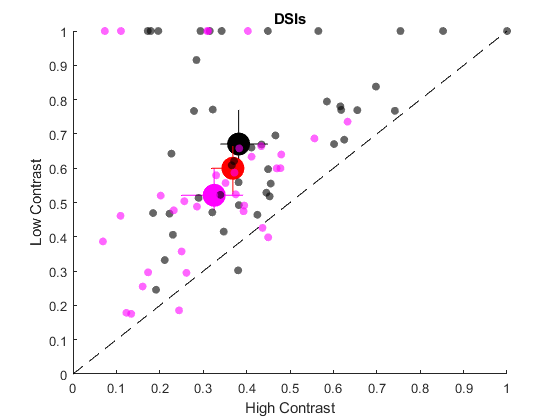


% figure
% title('DSI For High/Low Contrast')
% hold on
% for i = 1:numel(upDSIs)
%     p = plot([0.5, 1.5], [upDSIs(i), upDSIs_LowC(i)], 'Color', [0, 0, 0], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [0, 0, 0];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% for i = 1:numel(downDSIs)
%     p = plot([0.5, 1.5], [downDSIs(i), downDSIs_LowC(i)], 'Color', [1, 0, 1], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [1, 0, 1];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% xlim([0.3, 1.7])
% ylabel('DSI')
% xticks([0.5, 1.5])
% xticklabels({'High Contrast', 'Low Contrast'})
medianUpX = median(upDSIs);
medianUpY = median(upDSIs_LowC);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap(upDSIs, 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap(upDSIs_LowC, 10000);

medianDownX = median(downDSIs);
medianDownY = median(downDSIs_LowC);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap(downDSIs, 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap(downDSIs_LowC, 10000);

overallMedianX = median([upDSIs, downDSIs]);
overallMedianY = median([upDSIs_LowC, downDSIs_LowC]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upDSIs, downDSIs], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upDSIs_LowC, downDSIs_LowC], 10000);


figure
title('DSIs')
hold on
plot([0, 1], [0, 1], '--k')
scatter(medianUpX, medianUpY, 300, 'filled', 'k')
plot([-xUpER1, xUpER2]+medianUpX, [medianUpY, medianUpY], 'k')
plot([medianUpX, medianUpX], [-yUpER1, yUpER2] + medianUpY, 'k')
scatter(medianDownX, medianDownY, 300, 'filled', 'm')
plot([-xDownER1, xDownER2]+medianDownX, [medianDownY, medianDownY], 'm')
plot([medianDownX, medianDownX], [-yDownER1, yDownER2] + medianDownY, 'm')
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')

scatter(upDSIs, upDSIs_LowC, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downDSIs, downDSIs_LowC, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 1])
ylim([0, 1])

p_total =  signrank([upDSIs, downDSIs], [upDSIs_LowC, downDSIs_LowC])

p_total = 3.7302e-14

p_high = ranksum(upDSIs, downDSIs)

p_high = 0.0251

p_low = ranksum(upDSIs_LowC, downDSIs_LowC)

p_low = 0.0073

%proportion over unity for chi squared test with spikes:
overUnity_DSIs = [upDSIs downDSIs] > [upDSIs_LowC downDSIs_LowC];
proportion_DSIs = sum(overUnity_DSIs)/numel(overUnity_DSIs)

proportion_DSIs = 0.0500

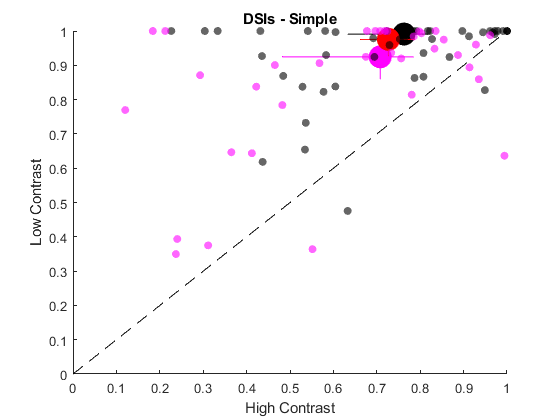



% figure
% title('Simple DSI For High/Low Contrast')
% hold on
% for i = 1:numel(upDSISimple)
%     p = plot([0.5, 1.5], [upDSISimple(i), upDSISimple_LowC(i)], 'Color', [0, 0, 0], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [0, 0, 0];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% for i = 1:numel(downDSISimple)
%     p = plot([0.5, 1.5], [downDSISimple(i), downDSISimple_LowC(i)], 'Color', [1, 0, 1], 'LineWidth', 1.5);
%     p.Marker = '.';
%     p.MarkerSize = 20;
%     p.MarkerFaceColor = [1, 0, 1];
%     p.MarkerEdgeColor = p.MarkerFaceColor;
% end
% xlim([0.3, 1.7])
% ylabel('Simple DSI')
% xticks([0.5, 1.5])
% xticklabels({'High Contrast', 'Low Contrast'})
medianUpX = median(upDSISimple);
medianUpY = median(upDSISimple_LowC);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap(upDSISimple, 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap(upDSISimple_LowC, 10000);

medianDownX = median(downDSISimple);
medianDownY = median(downDSISimple_LowC);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap(downDSISimple, 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap(downDSISimple_LowC, 10000);

overallMedianX = median([upDSISimple, downDSISimple]);
overallMedianY = median([upDSISimple_LowC, downDSISimple_LowC]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upDSISimple, downDSISimple], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upDSISimple_LowC, downDSISimple_LowC], 10000);



figure
title('DSIs - Simple')
hold on
plot([0, 1], [0, 1], '--k')
scatter(medianUpX, medianUpY, 300, 'filled', 'k')
plot([-xUpER1, xUpER2]+medianUpX, [medianUpY, medianUpY], 'k')
plot([medianUpX, medianUpX], [-yUpER1, yUpER2] + medianUpY, 'k')
scatter(medianDownX, medianDownY, 300, 'filled', 'm')
plot([-xDownER1, xDownER2]+medianDownX, [medianDownY, medianDownY], 'm')
plot([medianDownX, medianDownX], [-yDownER1, yDownER2] + medianDownY, 'm')
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')

scatter(upDSISimple, upDSISimple_LowC, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downDSISimple, downDSISimple_LowC, 'm' , 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 1])
ylim([0, 1])

p_total =  signrank([upDSISimple, downDSISimple], [upDSISimple_LowC, downDSISimple_LowC])

p_total = 1.2807e-11

p_high = ranksum(upDSISimple, downDSISimple)

p_high = 0.0808

p_low = ranksum(upDSISimple_LowC, downDSISimple_LowC)

p_low = 0.0235

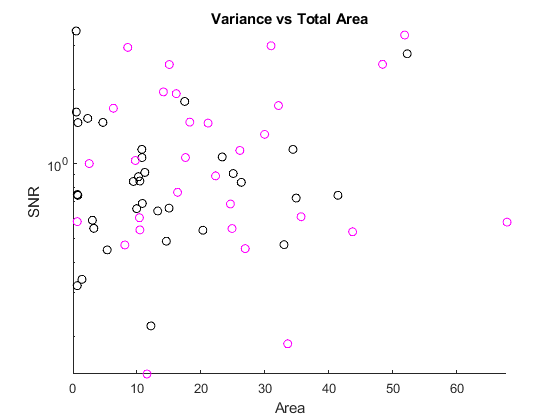


%Signal to Noise
figure
title('Variance vs Total Area')
hold on
scatter(upTCAreas_LowC, upTCAreas_LowC./upVariance_LowC, 'k')
scatter(downTCAreas_LowC,downTCAreas_LowC./downVariance_LowC, 'm')
xlabel('Area')
ylabel('SNR')
xlim([0 inf])
set(gca, 'YScale', 'log')

## Just the low contrast statistics as histograms

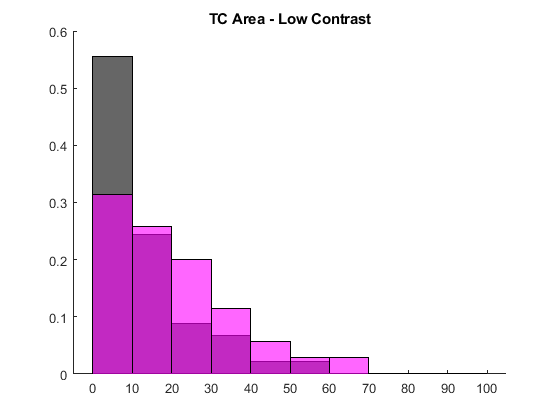

edgs = [0:10:100];
figure
title('TC Area - Low Contrast')
hold on
h1 = histogram(upTCAreas_LowC, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downTCAreas_LowC, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h1.BinEdges = edgs;
h2.BinEdges = edgs;

disp(['Median Up: ', num2str(median(upTCAreas_LowC)) ,'; Median Down: ', num2str(median(downTCAreas_LowC)),...
    '; p = ', num2str(ranksum(upTCAreas_LowC, downTCAreas_LowC))])

Median Up: 5.3375; Median Down: 16.3375; p = 0.0090634


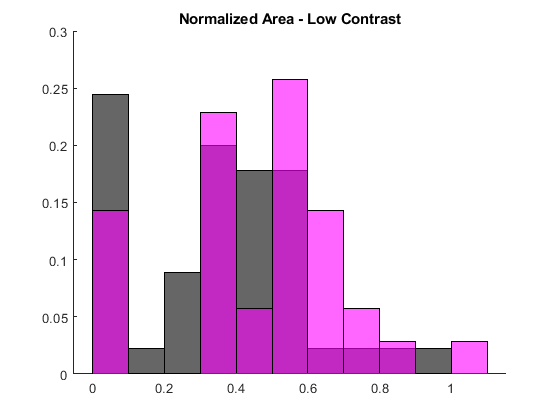

edgs = [0:0.1:1.1];
figure
title('Normalized Area - Low Contrast')
hold on
h1 = histogram(upNormedAreas_LowC, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downNormedAreas_LowC, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h1.BinEdges = edgs;
h2.BinEdges = edgs;

disp(['Median Up: ', num2str(median(upNormedAreas_LowC)) ,'; Median Down: ', num2str(median(downNormedAreas_LowC)),...
    '; p = ', num2str(ranksum(upNormedAreas_LowC, downNormedAreas_LowC))])

Median Up: 0.37252; Median Down: 0.51711; p = 0.0082001


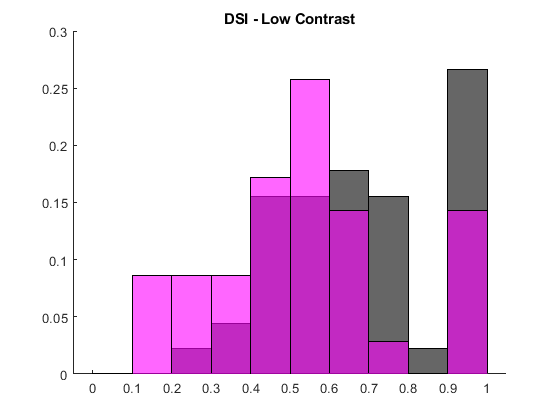

edgs = [0:0.1:1];
figure
title('DSI - Low Contrast')
hold on
h1 = histogram(upDSIs_LowC, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downDSIs_LowC, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h1.BinEdges = edgs;
h2.BinEdges = edgs;

disp(['Median Up: ', num2str(median(upDSIs_LowC)) ,'; Median Down: ', num2str(median(downDSIs_LowC)),...
    '; p = ', num2str(ranksum(upDSIs_LowC, downDSIs_LowC))])

Median Up: 0.67044; Median Down: 0.52102; p = 0.0073037


% figure
% scatter(log(upTCAreas_LowC), upNormedAreas_LowC, 'k', 'filled')
% hold on
% scatter(log(downTCAreas_LowC), downNormedAreas_LowC, 'm', 'filled')
% rmvOutliers_upTCAreas = upTCAreas(upNormedAreas < 1);
% rmvOutliers_upNormedAreas = upNormedAreas(upNormedAreas < 1);
% 
% rmvOutliers_downTCAreas = downTCAreas(downNormedAreas < 1);
% rmvOutliers_downNormedAreas = downNormedAreas(downNormedAreas < 1);
% 
% mdlUpAreas = fitlm(log(rmvOutliers_upTCAreas), rmvOutliers_upNormedAreas);
% mdlDownAreas = fitlm(log(rmvOutliers_downTCAreas), rmvOutliers_downNormedAreas);
% 
% fitQueries = [0.5:0.1:120];
% 
% upMdlPredictions = feval(mdlUpAreas, log(fitQueries));
% downMdlPredictions = feval(mdlDownAreas, log(fitQueries));
% 
% plot(log(fitQueries), upMdlPredictions, '--k', 'LineWidth', 1)
% plot(log(fitQueries), downMdlPredictions, '--m', 'LineWidth', 1)